# **ATD - Projeto 2024** 

# **META 1**

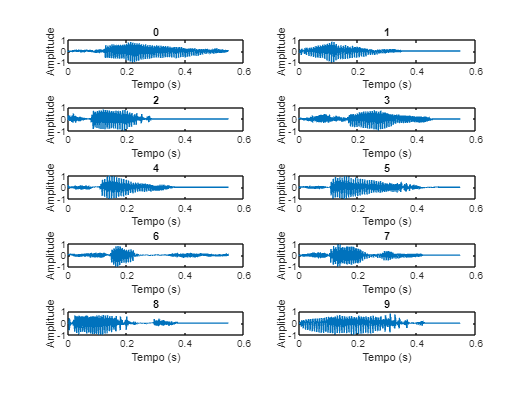

dados = ImportDataT();
dados10 = importData10(dados);

figure();
for num = 1 : 10
    criaGraf(dados10{num},num-1) 
end

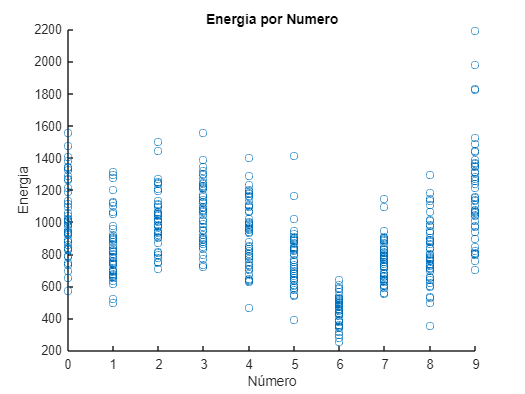

figure();
GrafEnergia(dados)

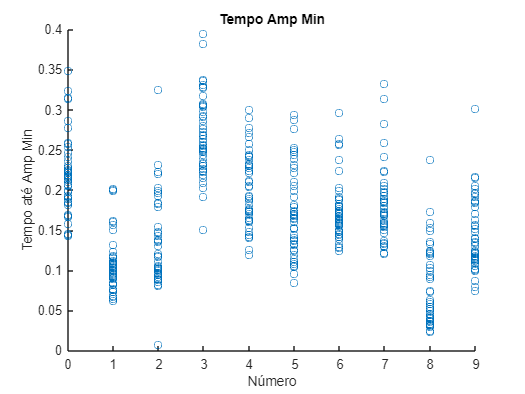

figure();
GrafAmpMax(dados);

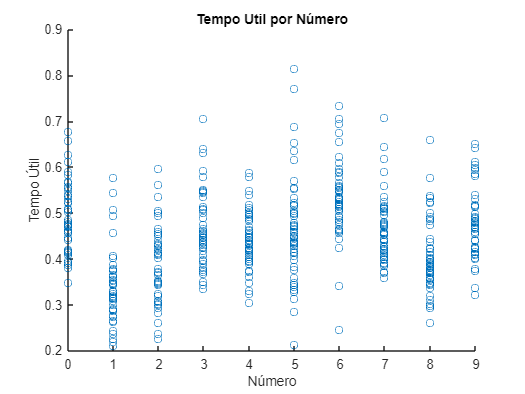

figure();
GrafTempUtil(dados);

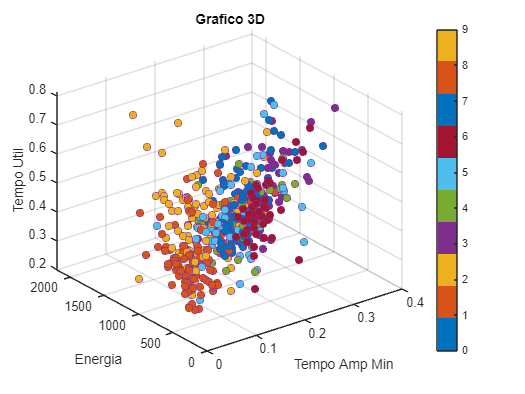

figure();
Graf3D(dados);

Escolheu-se como características, o **valor da energia por numero**, o **tempo até atingir a amplitude minima** e o** tempo de audio útil (sem ruido)**  uma vez que através das mesmas, é possível distinguir diferentes intensidades na pronuncia de numeros distintos, detetar padrões de pronuncia diferentes de digito para digito e visualizar o tempo que cada digito demora a ser totalmente pronunciado.

# **Meta 2**

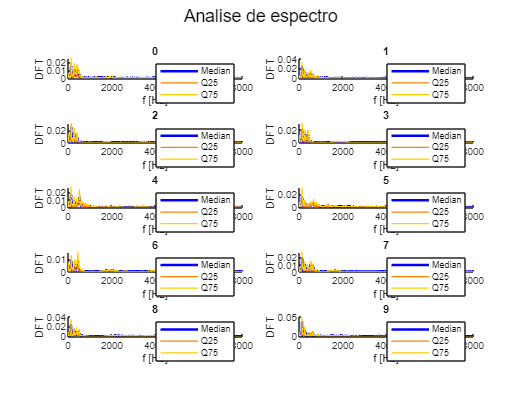

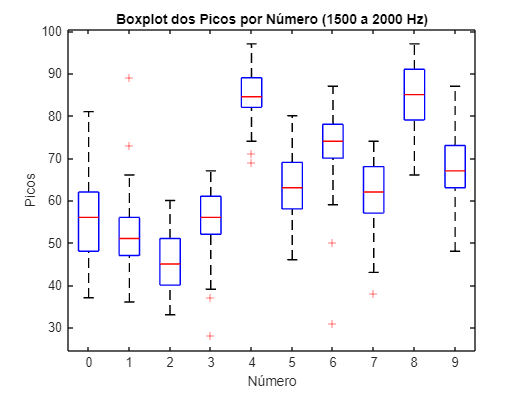

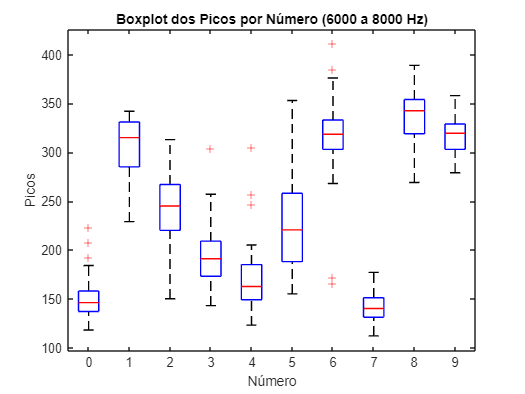

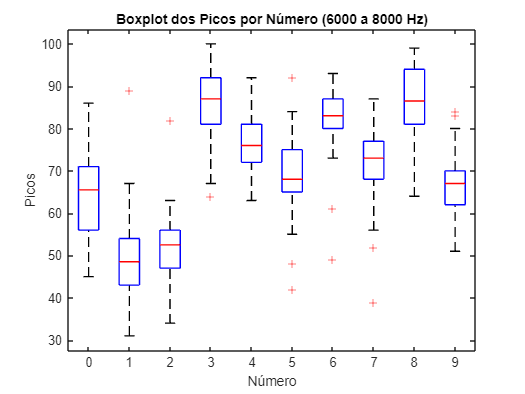

figure();
fft_caracteristicas(dados);

Nesta meta avaliaram-se várias características de modo a tentar recolher as três que mais distinguissem os nove diferentes dígitos. Após isto as três características escolhidas foram: **máximo espectral (amplitude)**, **energia por dígito **e **média espectral por dígito **que, conforme se pode verificar nos gráficos acima permitem distinguir os dígitos.

- **Máximo espectral (amplitude)**: Após obter cada espectro obtem-se a sua amplitude máxima, com as mesmas cria-se um gráfico Boxplot onde se comparam os diferentes dígitos.

- **Energia por dígito: **Através da soma da FFT ao quadrado, obteve-se a energia para cada dígito e do mesmo modo comparou-se os diferentes dígitos.

- **Média espectral por dígito: **Nesta característica obteve-se a media da amplitude dos espectros de cada digito e comparou-se os vários dígitos.

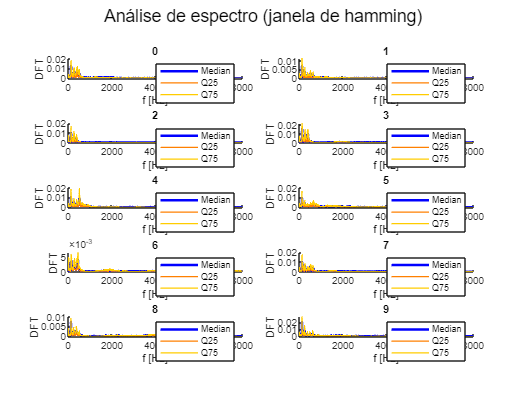

figure();
janelas(dados, 'hamming');

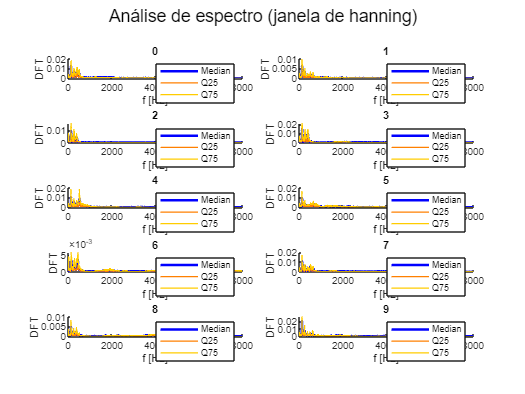


figure();
janelas(dados,'hanning');

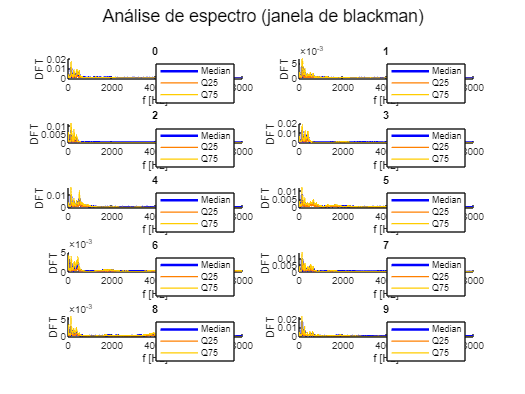

figure();
janelas(dados,'blackman');

Depois de serem aplicadas as diferentes janelas é possível verificar que em ambas as janelas houve alterações no eixo vertical, sendo que a janela de Hamming e Hanning apresentam alterações muito semelhantes. A maior diferença no eixo dos Y foi na janela de Blackman que comparativamente com o original apresentou uma escala mais reduzida.

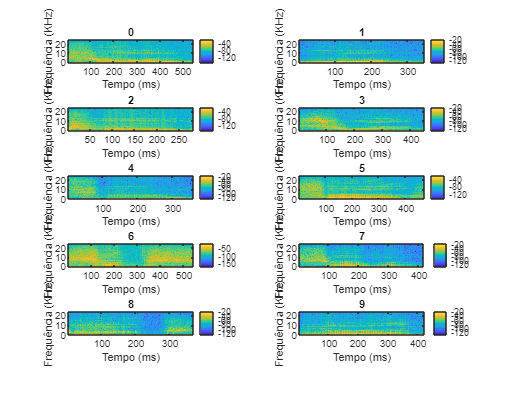

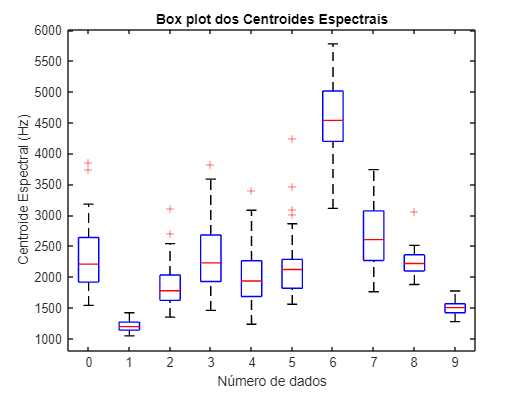

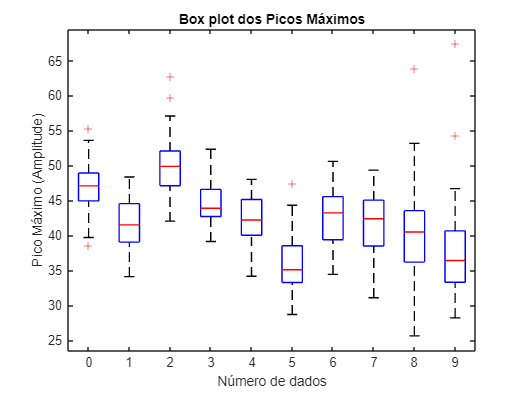

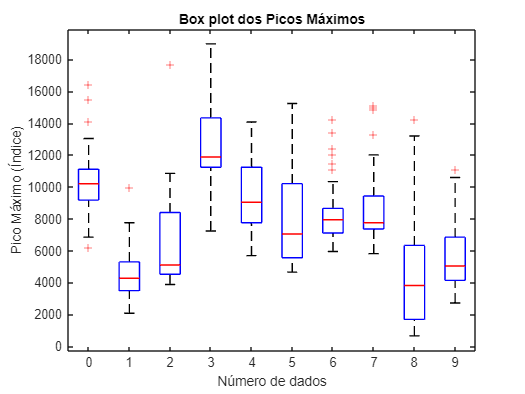

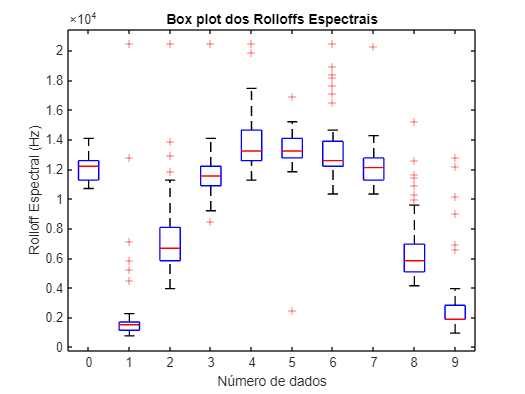

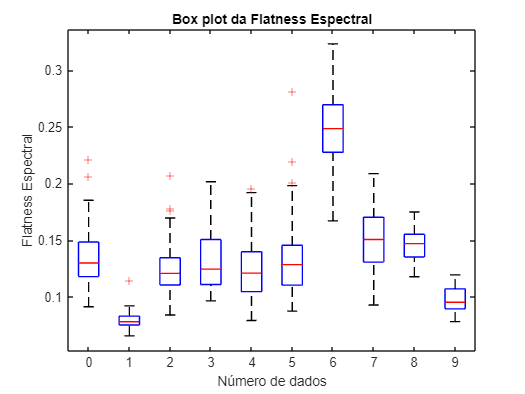

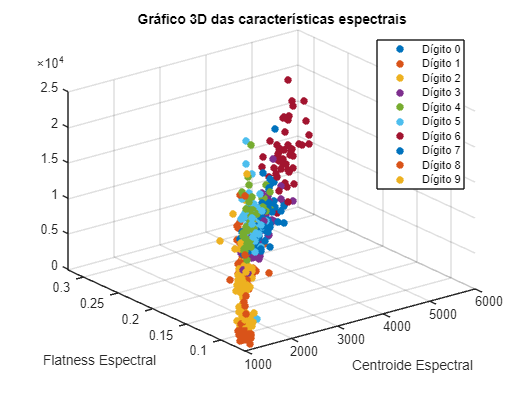

figure();
STFT(dados,dados10_s);

# **META 3**

## Espectograma

Para o cálculo do STFT, várias variáveis precisaram de uma parametrização como por exemplo o tamanho da janela, o tamanho da sobreposição das janelas e o número de pontos. Através de um ajuste destas variáveis foi possível concluir que se a dimensão da janela for reduzida a resolução aumenta, inversamente isso também ocorre.O numero de pontos para calcular o FFT deve ser igual ao tamanho da janela. Para o tamanho das sobreposições das janelas foi usado metade do tamanho da janela de forma a obter uma suavização da transição das janelas.

## Features

Com o intuíto de diferenciar os dígitos as features escolhidas foram:

**Centroides Espectrais: **O cálculo do centroide espectral permite calcular a média da frequência de um áudio, com base nessa média conseguimos perceber se um som é mais agudo ou mais grave. Através do cálculo dos centroides espectrais foi possível distinguir o dígito '6' e o dígito '1'.

**Picos Máximos por Amplitude:** O Máximo por Amplitude permite a distinção do ponto mais alto de um áudio.Através desta feature não conseguimos diferenciar nenhum dígito o que nos revela ser uma má feature para se usar de forma isolada.

**Picos Máximo por Índice: **Com o cálculo do Pico Máximo por Índice percebemos em que frequência ocorre o pico máximo. Através desta feature conseguimos diferenciar o dígitio '3'.

**Rollsoff Espectrais:**O Rollsoff Espectrais indica a frequência abaixo da qual está contida a maior parte da energia do som. Através desta feature é nos permitido diferenciar o dígito '1' e o dígito '9'. E ainda é possível diferenciar o dígito '2'  e o dígito' 8' dos restantes.

**Flatness Espectral:**Com a Flatness Espectral calculamos se um som tem picos ou se é uniforme.Através desta feature conseguimos distinguir o dígito '1' e o dígito '6'.

[numeros, indices] = distNum(dados, picos3, amp_min, t_util, centr, picos1, picos2 , ro, flat);

   39.2000



# **Meta 4**

No desenvolvimento da meta 4 nao conseguimos distinguir o quanto queriamos. Apesar das features calculadas serem muito boas, a percentagem que queriamos obter não foi atingida. Para o desenvolvimento do gráfico 3D usamos o rolloff, o flatness e o centroide que permitem distinguir alguns dígitos.